clear
clc

mu=0.01213;         %mass ratio for moon

coeff=[-1 mu+2 -2*mu-1 -mu+1 2*mu-2 1-mu];       %coefficients for polynomial to solve for L1 location

C=roots(coeff)

C =   -0.4946 + 0.8613i
  -0.4946 - 0.8613i
   1.0761 + 0.1457i
   1.0761 - 0.1457i
   0.8491 + 0.0000i



D=imag(C)

D =     0.8613
   -0.8613
    0.1457
   -0.1457
         0



D=abs(D)

D =     0.8613
    0.8613
    0.1457
    0.1457
         0



[~,I]=min(D)

I = 5


rs1=C(I)

rs1 = 0.8491


rs2=1-rs1

rs2 = 0.1509


xL1=rs1-mu

xL1 = 0.8370


yL1=0

yL1 = 0


%Jacobi Constant

rs1h=sqrt((xL1+mu)^2+yL1^2);
rs2h=sqrt((xL1-1+mu)^2+yL1^2);
C=2*((xL1^2+yL1^2)/2+(1-mu)/rs1h+mu/rs2h)

C = 3.1882


syms X Y
HC=(X.^2+Y.^2)+2.*(1-mu)./sqrt((X+mu).^2+Y.^2)+ ...
    2.*mu./sqrt((X-1+mu).^2+Y.^2)

$$HC = \frac{98787}{50000\,\sqrt{{\left(X+\frac{1213}{100000}\right)}^{2}+Y^{2}}}+\frac{1213}{50000\,\sqrt{{\left(X-\frac{98787}{100000}\right)}^{2}+Y^{2}}}+X^{2}+Y^{2}$$


%Linearization about L2 (in-plane only)

A=(1-mu)/rs1^3+mu/rs2^3

A = 5.1468


F=[0 0 1 0;
    0 0 0 1;
    1+2*A 0 0 2;
    0 1-A -2 0]

F =          0         0    1.0000         0
         0         0         0    1.0000
   11.2937         0         0    2.0000
         0   -4.1468   -2.0000         0



%Full state vector at L2
XL1=[xL1;
    yL1;
    0;
    0];

%eigendecomposition of F

[V,D]=eig(F)

V =   -0.2933 + 0.0000i  -0.2933 + 0.0000i   0.1058 - 0.0000i   0.1058 + 0.0000i
   0.1350 + 0.0000i  -0.1350 + 0.0000i   0.0000 + 0.3793i   0.0000 - 0.3793i
  -0.8598 + 0.0000i   0.8598 + 0.0000i  -0.0000 + 0.2469i  -0.0000 - 0.2469i
   0.3956 + 0.0000i   0.3956 + 0.0000i  -0.8854 + 0.0000i  -0.8854 + 0.0000i


D =    2.9318 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -2.9318 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 2.3342i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 2.3342i



%unstable manifold computation
epsilon=1e-6;
Xsp0=XL1+epsilon*real(V(:,2));
Xsn0=XL1-epsilon*real(V(:,2));
options=odeset('RelTol',1e-12,'AbsTol',1e-15);

[Tsp,Xsp] = ode45('pcrtbp_dyn',[0 20],Xsp0,options);
[Tsn,Xsn] = ode45('pcrtbp_dyn',[0 10],Xsn0,options);

figure(1)

plot(Xsp(:,1),Xsp(:,2),'b',Xsn(:,1),Xsn(:,2),'b--')
hold on


%add unstable eigenvectors projected on x-y plane
kk=0;
for ii=0:0.01:3,
    kk=kk+1;
    Eup(kk,:)=[XL1(1,1)+ii*real(V(1,2)) XL1(2,1)+ii*real(V(2,2))];
    Eun(kk,:)=[XL1(1,1)-ii*real(V(1,2)) XL1(2,1)-ii*real(V(2,2))];
end


plot(Eup(:,1),Eup(:,2),'r',Eun(:,1),Eun(:,2),'r--')
plot(-mu,0,'ko')
plot(1-mu,0,'k+')
plot(xL1,0,'rx')

fcontour(HC,[-1.5 2.5 -1.5 1.5],'k','MeshDensity',250,'LevelList',C)
leg1=legend('Interior Unstable Manifold','Exterior Unstable Manifold','Interior Unstable Eigenvector', 'Exterior Unstable Eigenvector', '$\hat{m}_1$','$\hat{m}_2$','$L_1$','Hill Curve')

leg1 =   Legend (Interior Unstable Manifold, Exterior Unstable Manifold, Interior Unstable Eigenvector, Exterior Unstable Eigenvector, $\hat{m}_1$, $\hat{m}_2$, $L_1$, Hill Curve) with properties:

         String: {'Interior Unstable Manifold'  'Exterior Unstable Manifold'  'Interior Unstable Eigenvector'  'Exterior Unstable Eigenvector'  '$\hat{m}_1$'  '$\hat{m}_2$'  '$L_1$'  'Hill Curve'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.5113 0.5663 0.3754 0.3340]
          Units: 'normalized'

  Show all properties


set(leg1,'Interpreter','latex')    
title('Unstable Manifolds')
xlabel('x')
ylabel('y')
% %evaluate Jacobi constant along trajectory
% 
% Nsp=length(Tsp);
% Nsn=length(Tsn);
% Csp=zeros(Nsp,1);
% Csn=zeros(Nsn,1);
% for ii=1:Nsp,
%     %distances to primaries
%     rs1h=sqrt((Xsp(ii,1)+mu)^2+Xsp(ii,2)^2);
%     rs2h=sqrt((Xsp(ii,1)-1+mu)^2+Xsp(ii,2)^2);
%     Csp(ii,1)=2*((Xsp(ii,1)^2+Xsp(ii,2)^2)/2+(1-mu)/rs1h+mu/rs2h)-Xsp(ii,3)^2-Xsp(ii,4)^2;
% end
% for ii=1:Nsn,
%     %distances to primaries
%     rs1h=sqrt((Xsn(ii,1)+mu)^2+Xsn(ii,2)^2);
%     rs2h=sqrt((Xsn(ii,1)-1+mu)^2+Xsn(ii,2)^2);
%     Csn(ii,1)=2*((Xsn(ii,1)^2+Xsn(ii,2)^2)/2+(1-mu)/rs1h+mu/rs2h)-Xsn(ii,3)^2-Xsn(ii,4)^2;
% end
% 
% figure(2)
% 
% plot(Tsp,Csp,'b',Tsn,Csn,'b--')


%stable manifold computation
epsilon=1e-6;
Xup0=XL1+epsilon*real(V(:,1));
Xun0=XL1-epsilon*real(V(:,1));


[Tup,Xup] = ode45('pcrtbp_dyn2',[0 10],Xup0,options);
[Tun,Xun] = ode45('pcrtbp_dyn2',[0 20],Xun0,options);

figure(3)

plot(Xun(:,1),Xun(:,2),'b',Xup(:,1),Xup(:,2),'b--')
hold on


%add unstable eigenvectors projected on x-y plane
kk=0;
for ii=0:0.01:3,
    kk=kk+1;
    Esp(kk,:)=[XL1(1,1)+ii*real(V(1,1)) XL1(2,1)+ii*real(V(2,1))];
    Esn(kk,:)=[XL1(1,1)-ii*real(V(1,1)) XL1(2,1)-ii*real(V(2,1))];
end

plot(Esn(:,1),Esn(:,2),'r',Esp(:,1),Esp(:,2),'r--')
plot(-mu,0,'ko')
plot(1-mu,0,'k+')
plot(xL1,0,'rx')
fcontour(HC,[-1.5 2.5 -1.5 1.5],'k','MeshDensity',250,'LevelList',C)
leg2=legend('Interior Stable Manifold','Exterior Stable Manifold','Interior Stable Eigenvector', 'Exterior Stable Eigenvector', '$\hat{m}_1$','$\hat{m}_2$','$L_1$','Hill Curve')

leg2 =   Legend (Interior Stable Manifold, Exterior Stable Manifold, Interior Stable Eigenvector, Exterior Stable Eigenvector, $\hat{m}_1$, $\hat{m}_2$, $L_1$, Hill Curve) with properties:

         String: {'Interior Stable Manifold'  'Exterior Stable Manifold'  'Interior Stable Eigenvector'  'Exterior Stable Eigenvector'  '$\hat{m}_1$'  '$\hat{m}_2$'  '$L_1$'  'Hill Curve'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.5365 0.6082 0.3502 0.2921]
          Units: 'normalized'

  Show all properties


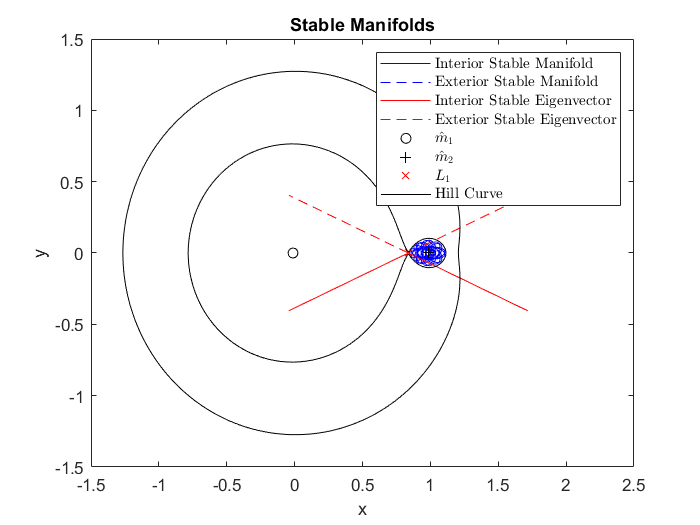

set(leg2,'Interpreter','latex')      
title('Stable Manifolds')
xlabel('x')
ylabel('y')

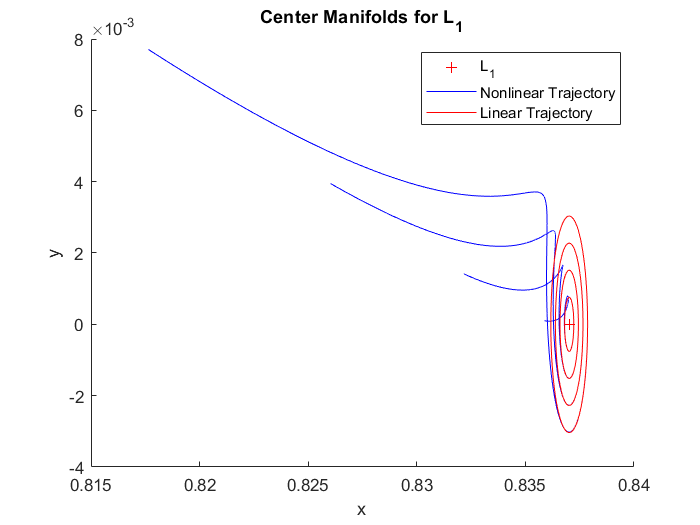

% %evaluate Jacobi constant along trajectory
% 
% Nup=length(Tup);
% Nun=length(Tun);
% Cup=zeros(Nup,1);
% Cun=zeros(Nun,1);
% for ii=1:Nup,
%     %distances to primaries
%     rs1h=sqrt((Xup(ii,1)+mu)^2+Xup(ii,2)^2);
%     rs2h=sqrt((Xup(ii,1)-1+mu)^2+Xup(ii,2)^2);
%     Cup(ii,1)=2*((Xup(ii,1)^2+Xup(ii,2)^2)/2+(1-mu)/rs1h+mu/rs2h)-Xup(ii,3)^2-Xup(ii,4)^2;
% end
% for ii=1:Nun,
%     %distances to primaries
%     rs1h=sqrt((Xun(ii,1)+mu)^2+Xun(ii,2)^2);
%     rs2h=sqrt((Xun(ii,1)-1+mu)^2+Xun(ii,2)^2);
%     Cun(ii,1)=2*((Xun(ii,1)^2+Xun(ii,2)^2)/2+(1-mu)/rs1h+mu/rs2h)-Xun(ii,3)^2-Xun(ii,4)^2;
% end


% %test of stable manifold (start at end point from backwards integration and
% %propagate forwards)
% X0=Xup(Nup,:).';
% [T,X] = ode45('pcrtbp_dyn',[0 20],X0,options)
% X0=Xun(Nun,:).';
% [T2,X2] = ode45('pcrtbp_dyn',[0 20],X0,options)
% figure(5)
% 
% plot(X(:,1),X(:,2),'b',X2(:,1),X2(:,2),'b--')
% hold on
% plot(-mu,0,'ko')
% plot(1-mu,0,'ko')
% plot(xL2,0,'r+')


%center manifold trajectory

%frequency
om=imag(D(3,3));

%real and imaginary parts of corresponding eigenvector
uR=real(V(:,3));
uI=imag(V(:,3));

%set phase to zero (phi=0)
%range of amplitudes rho varies between 0.05 to 0.2

figure(6)
hold on
%plot(1-mu,0,'ko')
plot(xL1,0,'r+')
for rho=0.001:0.001:0.004,
    
    %trajectory from linearization
    kk=0;
    for t=0:0.01:3,
        kk=kk+1;
        Tlin(kk,1)=t;
        Xclin(kk,:)=(XL1+2*rho*(cos(om*t)*uR-sin(om*t)*uI)).';
    end
    
    %trajectory for full nonlinear system
    %initial condition
    Xc0=XL1+2*rho*uR;
    [Tc,Xc] = ode45('pcrtbp_dyn',[0 3],Xc0,options);
    
    
    plot(Xc(:,1),Xc(:,2),'b',Xclin(:,1),Xclin(:,2),'r')
    
    
end
xlabel('x')
ylabel('y')
title('Center Manifolds for L_1')
legend('L_1','Nonlinear Trajectory','Linear Trajectory')